# Sesión 5: Convergencia de los métodos iterativos

## Convergencia

### Diagonal estrictamente dominante

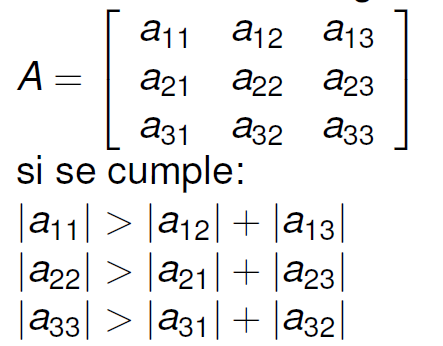

A = [3 1 0; 
    -1 3 -1; 
    0 1 -3]

A =      3     1     0
    -1     3    -1
     0     1    -3


f1=abs(A(1,:))

f1 =      3     1     0


f1(1) > sum(f1(2:end)) % V

ans = logical
   1



f2=abs(A(2,:))

f2 =      1     3     1


f2(2) > sum(f2)-f2(2) % V

ans = logical
   1



f3=abs(A(3,:))

f3 =      0     1     3


f3(3) > sum(f3)-f3(3) % V

ans = logical
   1


Fila: Ax=b

a_{ii} > resto de a_{ij}

a_{ii} + a_{ii} > resto de a_{ij} + a_{ii}

2*a_{ii} > toda la fila i

A

A =      3     1     0
    -1     3    -1
     0     1    -3


2*abs(A(1,1)) > sum(abs(A(1,:)))

ans = logical
   1


2*diag(abs(A)) > sum(abs(A),2)

ans = 3×1 logical array
   1
   1
   1


Caso del ejemplo

A = [10 -1 2 0;...
    -1 11 -1 3;...
    2 -1 10 -1;...
    0 3 -1 8];
2*diag(abs(A)) > sum(abs(A),2)

ans = 4×1 logical array
   1
   1
   1
   1


op = diagdom(A) 

op = 1

op = 0;
if op == 1
    disp('Jacobi y Gauss-Seidel convergen')
elseif op == 0
    disp('no se sabe si hay convergencia')
end

no se sabe si hay convergencia


Caso de ejercicio

syms p q
A = [1 2 p; 0 q -4; 0 0 0.5]

$$A = \left(\begin{array}{ccc} 1 & 2 & p\\ 0 & q & -4\\ 0 & 0 & \frac{1}{2} \end{array}\right)$$

f1=abs(A(1,:))

$$f1 = \left(\begin{array}{ccc} 1 & 2 & \left|p\right| \end{array}\right)$$

f1(1) > sum(f1(2:end)) % Falso -> A no es diagonal estrictamente dominante

$$ans = \left|p\right|+2<1$$

op = 0;
if op == 1
    disp('Jacobi y Gauss-Seidel convergen')
elseif op == 0
    disp('no se sabe si hay convergencia')
end

no se sabe si hay convergencia


#### Radio espectral

El método iterativo con matriz $T$converge *sí y solo sí* $\rho(T) < 1$.

Aquí, $\rho(T)$ es el radio espectral de la matriz de iteración $T$:


$$\rho(T) =  \max \{|\lambda|: \lambda ~\mbox{valor propio de} ~T\}= \max \{|\lambda|: ~\det(T-\lambda I)\}$$


A = [3 1 0; 
    1 3 1; 
    0 1 3]

A =      3     1     0
     1     3     1
     0     1     3


% Iteración de Jacobi
D=diag(diag(A)); L=-tril(A,-1); U=-triu(A,1);
T_j=inv(D)*(L+U);
Lambda = eig(T_j)

Lambda =    -0.4714
    0.0000
    0.4714


rho = max(abs(Lambda)) % < 1, hay convergencia de Jacobi

rho = 0.4714

% converge Gauss-Seidel con el criterio de radio espectral?
T_gs=inv(D-L)*(U);
Lambda = eig(T_gs)

Lambda =          0
    0.2222
         0


rho = max(abs(Lambda)) % < 1, hay convergencia de Gauss-Seidel

rho = 0.2222

Caso del ejemplo

A = [10 -1 2 0;...
    -1 11 -1 3;...
    2 -1 10 -1;...
    0 3 -1 8];

method = 0; % Jacobi
[op,r] = convergente(A,method)

op = 1

r = 0.4264

if op == 1
    disp('Jacobi converge')
else
    disp('Jacobi no converge')
end

Jacobi converge



method = 1; % Gauss-Seidel
[op,r] = convergente(A,method)

op = 1

r = 0.0898

if op == 1
    disp('Gauss-Seidel converge')
else
    disp('Gauss-Seidel no converge')
end

Gauss-Seidel converge


Caso de ejercicio

syms p q
B = [1 2 10; p q -4; 0 p -4] % Bx=b

$$B = \left(\begin{array}{ccc} 1 & 2 & 10\\ p & q & -4\\ 0 & p & -4 \end{array}\right)$$


%p_val=0.2; q_val=1; % convergencia
p_val=-1; q_val=1; % Jacobi no converge

A = double(subs(B,[p,q],[p_val,q_val])) % Ax=b

A =      1     2    10
    -1     1    -4
     0    -1    -4



method = 0; % Jacobi
[op,r] = convergente(A,method)

op = 0

r = 1.8729

if op == 1
    disp('Jacobi converge')
else
    disp('Jacobi no converge')
end

Jacobi no converge



method = 1;
[op,r] = convergente(A,method)

op = 1

r = 0.5000

if op == 1
    disp('Gauss-Seidel converge')
else
    disp('Gauss-Seidel no converge')
end

Gauss-Seidel converge


## Sobre normas y convergencia

### Normas vectoriales

Norma euclideana

                        
$${\| v\|}_2=\sqrt{v_1^2+v_2^2\cdots+v_d^2}$$


v = [1:7]

v =      1     2     3     4     5     6     7


norm(v)

ans = 11.8322

Norma infinito 

                        
$${\| v\|}_\infty=\max\{ |v_1|,|v_2|,\dots,|v_d| \}$$


v = [-4:1:3]

v =     -4    -3    -2    -1     0     1     2     3


norm(v,inf)

ans = 4

Norma de la suma

                        
$${\| v\|}_1=|v_1|+|v_2|+\dots+|v_d|$$


v = [1:7]

v =      1     2     3     4     5     6     7


norm(v,1)

ans = 28

v = [-4:1:3]

v =     -4    -3    -2    -1     0     1     2     3


norm(v,1)

ans = 16

Relaciones

                        
$${\| v\|}_\infty \le  {\| v\|}_2 \le  {\| v\|}_1 \le \sqrt{d} {\| v\|}_2 \le d {\| v\|}_\infty$$


### Normas matriciales

Norma infinito

                        
$${\| A\|}_\infty=\max\{ {\| a\|}_1 : ~a ~\mbox{fila de} ~A \}$$


A = [1 4;
    2 2]

A =      1     4
     2     2


norm(A,inf)

ans = 5

A = [3 2;
    1 -4]

A =      3     2
     1    -4


norm(A,inf)

ans = 5

Norma de la suma

                        
$${\| A\|}_1=\max\{ {\| a\|}_1 : ~a ~\mbox{columna de} ~A \}$$


A = [1 4;
    2 2];
norm(A,1)

ans = 6

A = [3 2;
    1 -4];
norm(A,1)

ans = 6

### Criterio de convergencia del método de punto fijo

Tenemos $\left[ \begin{array}{c}
x) \\
y 
\end{array} \right] = 
\mathbf{x}=G(\mathbf{x})=
\left[ \begin{array}{c}
u(x,y) \\
v(x,y) 
\end{array} \right]  = 
\left[ \begin{array}{c}
\frac{x}{2} - \frac{y}{4} \\
\frac{\ln(x)}{2} + \frac{\sin(y)}{5} 
\end{array} \right] $

Luego,

$\left\{
\begin{array}{c}
\left|\frac{\partial u}{\partial x} (x^0,y^0) \right| + \left|\frac{\partial u}{\partial y} (x^0,y^0) \right| <1 \\
\left|\frac{\partial u}{\partial x} (x^0,y^0) \right| + \left|\frac{\partial u}{\partial y} (x^0,y^0) \right| <1
\end{array}
\right.$    si y solo si    ${\left\| J_G(x^0,y^0) \right\|}_\infty < 1$

G = @(w) [w(1)/2-w(2)/4;
    log(w(1))/2+sin(w(2))/5]

G = function_handle with value:
    @(w)[w(1)/2-w(2)/4;log(w(1))/2+sin(w(2))/5]


syms x y
G([x; y])

$$ans = \left(\begin{array}{c} \frac{x}{2}-\frac{y}{4}\\ \frac{\log\left(x\right)}{2}+\frac{\sin\left(y\right)}{5} \end{array}\right)$$

dJ = jacobian(G([x; y]))

$$dJ = \left(\begin{array}{cc} \frac{1}{2} & -\frac{1}{4}\\ \frac{1}{2\,x} & \frac{\cos\left(y\right)}{5} \end{array}\right)$$

norm(dJ,inf) % norma matricial

$$ans = \max\left(\frac{3}{4},\frac{\left|\cos\left(y\right)\right|}{5}+\frac{1}{2\,\left|x\right|}\right)$$

x0=1; y0=0;
A = double(subs(dJ,[x,y],[x0,y0])) % se evalúa semilla

A =     0.5000   -0.2500
    0.5000    0.2000


norm(A,inf)

ans = 0.7500

function [z,T,c]=iterativo(A,b,x0,Tol,method)
% Entrada
% method: variable numérica
% method=0: Jacobi
% method=1: Gauss-Seidel

% Construir T, c
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);

if method==0
    % Jacobi
    T=inv(D)*(L+U);
    c=inv(D)*b;
elseif method==1
    % Gauss-Seidel
    T=inv(D-L)*(U);
    c=inv(D-L)*b;    
else
    error('Escoja un método válido: 0 (Jacobi), 1 (Gauss-Seidel)')
end

% Inicialización
k=0;
er=1;
z=[k x0' NaN];

while er > Tol
    k=k+1;
    x1=T*x0+c;
    er=norm(x1-x0,inf)/norm(x1,inf);
    z=[z;k x1' er];
    x0=x1;
end
end

function op=diagdom(A)
% Salida
% op=1: diagonal estrictamente dominante
% op=0: no diagonal estrictamente dominante
    op=double(all( 2*diag(abs(A)) > sum(abs(A),2) ));
end

function [op,r]=convergente(A,method)
% Entrada
% method=0: Jacobi
% method=1: Gauss-Seidel
% Salida
% op=1: convergente
% op=0: no convergente

% Construir T, c
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);

if method==0
    T=inv(D)*(L+U); % Jacobi
elseif method==1
    T=inv(D-L)*(U); % Gauss-Seidel
end

r = max(abs(eig(T)));
op = double(r < 1);
end